# Punto 2

# a).

#### Para calcular cuánto tiempo durará la forma de onda completa, necesitamos conocer la duración total del score y la frecuencia de muestreo que utilizarás para generar la forma de onda. Una vez de haber obtenido esta información, podemos calcular el número de muestras que necesitas para representar toda la forma de onda y, por lo tanto, reservar memoria suficiente.

% duración total del score
%total_d = sum(nd);

% Frecuencia de muestreo
%Fs = 8000;                                -> Frecuencia de muestreo
%t_tot = linspace(0, total_d, Fs*total_d); -> vector de tiempos

#### Para evitar quedarnos sin memoria, podemos generar y agregar las notas en lotes pequeños en lugar de agregar todo el score a la vez. 

# b). 

#### Mantenga un seguimiento de donde debe agregarse la siguiente nota en el gran vector.

% Canciones (gran vector)
%song = zeros(1, length(t_tot));

%momento_actual = 1;

%momento_siguiente = length(nota_i) + momento_actual -1; % para reproducir sucesivamente la siguiente nota
%song(momento_actual:momento_siguiente) = nota_i;
%momento_actual = momento_siguiente;

#### Una vez con las ideas en mente, se procedió a desarollar el programa. El código final de mkmusic.m para generar una forma de onda para el score completo y después almacenarlo en su forma de onda como archivo .wav, es el siguiente:

# Código mkmusic.m final - Ejemplo Ode To Joy

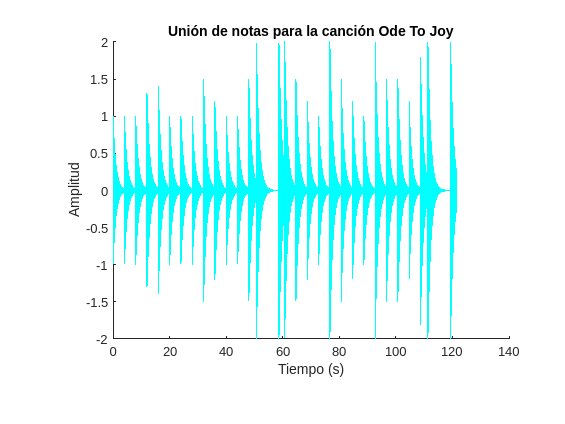

clear;

% Cargar la definición de notas 
notes;

% Carga la partitura
odetojoy; 

% duración total de todas las notas
total_d = sum(nd);

% Configuración de la generación de audio
Fs = 8000;                                  % Frecuencia de muestreo
t_tot = linspace(0, total_d, Fs*total_d);   % vector de tiempos

% Canciones (vector grande)
song = zeros(1, length(t_tot));

tau = 1;                                    % cte de tiempo que controla la rapidez con la que la envolvente decae
ha = [1 1 1 1];

momento_actual = 1;

for i = 1:length(nf)
    
    t = linspace(0, nd(i), Fs*nd(i));                       % vector de tiempo
    env = exp(-t/tau);                                      % envolvente exponencial

    nota_i = mknote(nf(i), 1, na(i), ha, env, t);           % nota a reproducir

    momento_siguiente = length(nota_i) + momento_actual -1; % para reproducir sucesivamente la siguiente nota
    song(momento_actual:momento_siguiente) = nota_i;
    momento_actual = momento_siguiente;

end

% Grafica la forma de onda de la nota
set(subplot(3,1,1),'Position',[0.2 0.2 0.7 0.7]);
hold on;
plot(t_tot, song, 'c');               
hold off;
xlabel('Tiempo (s)'); ylabel('Amplitud'); title('Unión de notas para la canción Ode To Joy');

# Ejemplo con mornmood

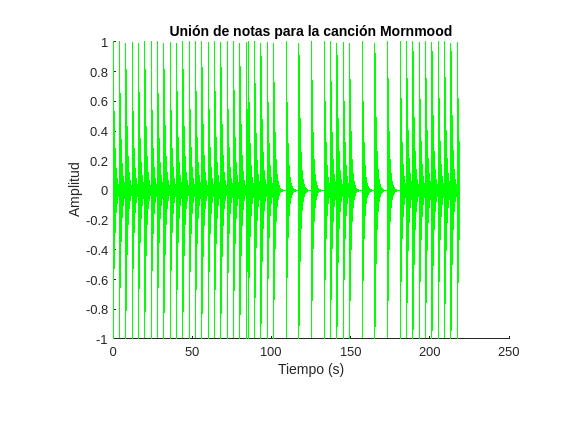

clear;

% Cargar la definición de notas 
notes;

% Carga la partitura
mornmood; 

% duración total de todas las notas
total_d = sum(nd);

% Configuración de la generación de audio
Fs = 8000;                                  % Frecuencia de muestreo
t_tot = linspace(0, total_d, Fs*total_d);   % vector de tiempos

% Canciones (vector grande)
song2 = zeros(1, length(t_tot));

tau = 1;                                    % cte de tiempo que controla la rapidez con la que la envolvente decae
ha = [1 1 1 1];

momento_actual = 1;

for i = 1:length(nf)
    
    t = linspace(0, nd(i), Fs*nd(i));                       % vector de tiempo
    env = exp(-t/tau);                                      % envolvente exponencial

    nota_i = mknote(nf(i), 1, na(i), ha, env, t);           % nota a reproducir

    momento_siguiente = length(nota_i) + momento_actual -1; % para reproducir sucesivamente la siguiente nota
    song2(momento_actual:momento_siguiente) = nota_i;
    momento_actual = momento_siguiente;

end

% Grafica la forma de onda de la nota
set(subplot(3,1,2),'Position',[0.2 0.2 0.7 0.7]);
hold on;
plot(t_tot, song2, 'g');       
hold off;
xlabel('Tiempo (s)'); ylabel('Amplitud'); title('Unión de notas para la canción Mornmood');

# Ejemplo con Furelise

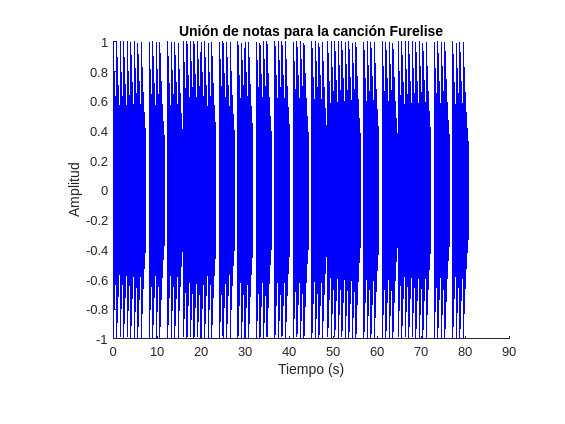

clear;

% Cargar la definición de notas 
notes;

% Carga la partitura
furelise; 

% duración total de todas las notas
total_d = sum(nd);

% Configuración de la generación de audio
Fs = 8000;                                  % Frecuencia de muestreo
t_tot = linspace(0, total_d, Fs*total_d);   % vector de tiempos

% Canciones (vector grande)
song3 = zeros(1, length(t_tot));

tau = 1;                                    % cte de tiempo que controla la rapidez con la que la envolvente decae
ha = [1 1 1 1];

momento_actual = 1;

for i = 1:length(nf)
    
    t = linspace(0, nd(i), Fs*nd(i));                       % vector de tiempo
    env = exp(-t/tau);                                      % envolvente exponencial

    nota_i = mknote(nf(i), 1, na(i), ha, env, t);           % nota a reproducir

    momento_siguiente = length(nota_i) + momento_actual -1; % para reproducir sucesivamente la siguiente nota
    song3(momento_actual:momento_siguiente) = nota_i;
    momento_actual = momento_siguiente;

end

% Grafica la forma de onda de la nota
set(subplot(3,1,2),'Position',[0.2 0.2 0.7 0.7]);
hold on;
plot(t_tot, song3, 'b');       
hold off;
xlabel('Tiempo (s)'); ylabel('Amplitud'); title('Unión de notas para la canción Furelise');

#### Para el ejemplo de Furelise realizamos dos versiones, la primera (furelise.wav) con las duraciones de nota que se propone en el laboratorio, y la segunda (furelise2.wav) con duraciones propuestas por nosostras para que el resultado se asimilara más a la canción original.

function n = mknote(nf, nd, ns, ha, env, t)
    t2 = zeros(size(t));
    t2(1:nd*length(t)) = t(1:nd*length(t));

    harm = zeros(size(t));

    for i = 1:length(ha)
        harm = harm + ha(i)*sin(2*pi*i*nf*t2);
    end

    n = harm.*env;    
    n = ns*n/max(abs(n));
end

#### `Nota`: Todas las canciones generadas .wav van a estar guardadas en una carpeta a parte.

#### Y así hemos concluido con el Taller.